clear;
height = 100;
width = 100;
hold on
qstart = [10 50];
qgoal = [90 50];
axis ([0 width 0 height]);
b=eudist(qstart,qgoal);

slop = abs(qgoal(2)-qstart(2))/(qgoal(1)-qstart(1))

slop =      0


qcenter = [qstart(1)+(((qgoal(1)-qstart(1))/b)*(b/2)),qstart(2)+(((qgoal(2)-qstart(2))/b)*(b/2))];
rotation = [cos(slop) sin(slop);sin(slop) cos(slop)]

rotation =      1     0
     0     1


m = 1000;
for i=1:5000
x1 = randn(1,2);
x2=x1*[b^(1/2) 0.5;0.5 5];



x3=x2*rotation;
x(i,:) = x3+qcenter;
end
%figure;
%plot([qstart(1),qgoal(1)],[qstart(2),qgoal(2)])
y=[cos(slop) -sin(slop)]

y =      1     0


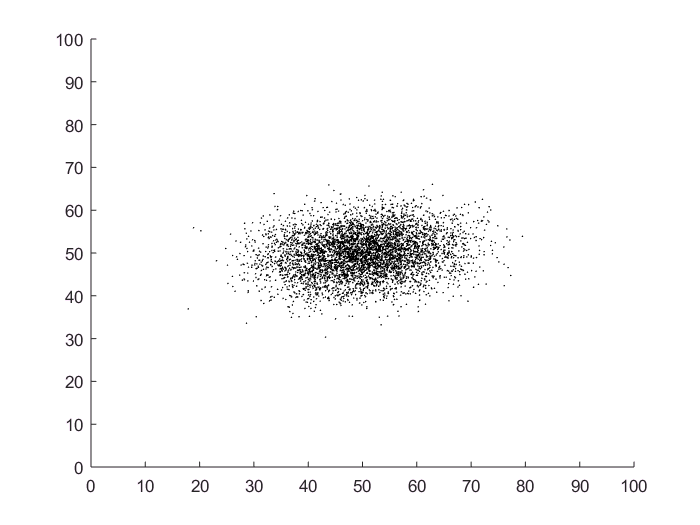

a1=qstart*rotation;
a2=qgoal*rotation;
%plot([a1(1),a2(1)],[a1(2),a2(2)])
plot(x(:,1),x(:,2),'k.','MarkerSize',3)